%% Paper 

The Length of the Shortest Telomere as the Major

Determinant of the Onset of Replicative Senescence 

TL distribution

clear all; clc ;

%Parameters
% From (Teixeira et al. 2004)
p = 0.026;
beta = 0.045;
L0 = 90;        % Initial Critical Length
a = 3;          % 3 or 4 Shortening rate with probability 0.5
n = 100;        % No. of divisions
Tel = 10000;    % No. of Telomeres

Equations

L(n+1) = L(n) - a;     % w.p. 1-P(Ln)

L(n+1) = L(n) - a + b; % w.p. P(Ln)

where Ln+1 is length at next division

a is mean shortening rate ~ (3-4) bp 

b is telomerase processivity

L = []; % to store Length at each division
T = zeros([Tel,n]); % # of independent telomeres for n division
Tp = zeros([Tel,n]); % Telomerase processivity for telomeres
initlen = 200; % This is starting-/initial length with 200bp
finlen = 400; % This is ending/finishing length with 400 bp
sslen = (finlen-initlen).*rand(100000,1) + initlen; % uniform distribution
B = []; % array to store Telomerase processivity values
PLN = [];
T_avg = zeros(5,n);
Hist_Tel = [];

% Parameters for graph
Telpro = [20 30 38.6 50 60];
Prob_arr = [0.05 0.075 0.09 0.125 0.15];

% Loop

for k = 1:5  % Change k with a for different a values also at end of loop
    
    %p = Prob_arr(a);
    %p = Prob_arr(k);
    %beta = Prob_arr(k);
    for t =1:Tel

    %Initial length from distribution for each telomere
        L(1) = sslen(t);
        %L(1) = 140;
        for i=1:n-1
            % Generating b from geometric distribution with prob p
            b = geornd(p); % Telomerase processivity % Takes maximum time
            %of execution
            %b = Telpro(k);
            B(i+1) = b;
            if (L(i)>=L0)
                %Probability of elongation
                PLn = 1/ (1 + beta*(L(i)-L0));
            else
                PLn = 1;
            end
            if (PLn > rand)
                L(i+1) = (L(i) -a+b);
            else
                L(i+1) = (L(i) - a);
            end
            %L(i+1) = (L(i) - a)*(1-PLn) + (L(i) - a + b)*PLn;
        end
        T(t,:) = L;
        Tp(t,:) = B;
        Hist_Tel(t) = L(end);
    end
    T_avg(k,:) = mean(T); % Change k with a
end

Plot graphs

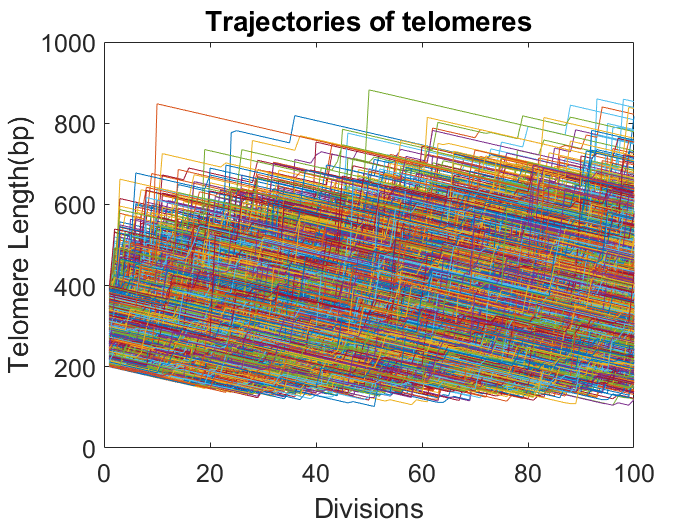

figure(1);
plot(1:n,T);
ax = gca;
ax.FontSize = 15;
xlabel("Divisions",'Fontsize',15);
ylabel("Telomere Length(bp)",'Fontsize',15);
title("Trajectories of telomeres");

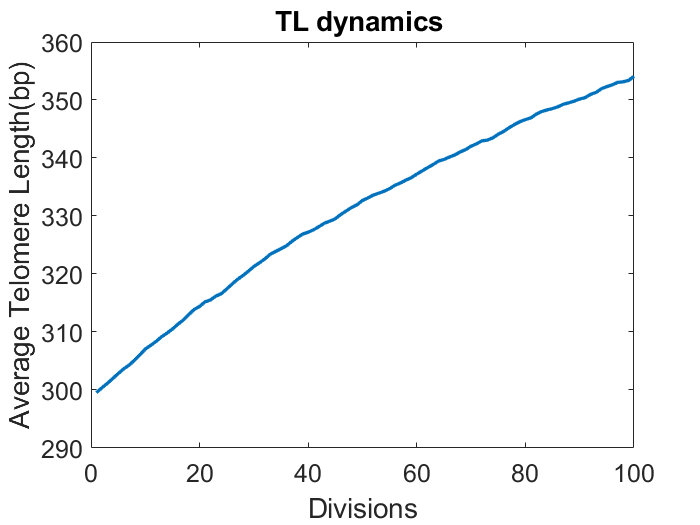

figure(2);
TL_avg = mean(T);
plot(TL_avg,'linewidth',2);
ax = gca;
ax.FontSize = 15;
xlabel("Divisions",'FontSize',15);
ylabel("Average Telomere Length(bp)","FontSize",15);
title("TL dynamics ");

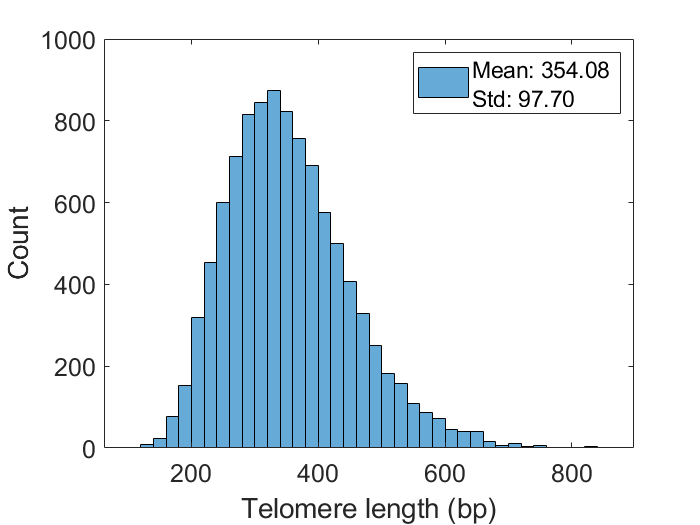

h_mu = mean(Hist_Tel);
%h_var = var(Hist_Tel);
h_std = std(Hist_Tel);
figure(3);
histogram(Hist_Tel);
ax = gca;
ax.FontSize = 15;
xlabel("Telomere length (bp)","FontSize",15);
ylabel("Count",'FontSize',15);
legend(sprintf('Mean: %0.2f \nStd: %0.2f',h_mu,h_std));

%title(sprintf('TL Mean %0.2f, Std = %0.2f',h_mu,h_std));


% Loop

for a = 1:5  % Change k with a for different a values also at end of loop
    
    %p = Prob_arr(a);
    %p = Prob_arr(k);
    %beta = Prob_arr(k);
    for t =1:Tel

    %Initial length from distribution for each telomere
        L(1) = sslen(t);
        %L(1) = 140;
        for i=1:n-1
            % Generating b from geometric distribution with prob p
            b = geornd(p); % Telomerase processivity % Takes maximum time
            %of execution
            %b = Telpro(k);
            B(i+1) = b;
            if (L(i)>=L0)
                %Probability of elongation
                PLn = 1/ (1 + beta*(L(i)-L0));
            else
                PLn = 1;
            end
            if (PLn > rand)
                L(i+1) = (L(i) -a+b);
            else
                L(i+1) = (L(i) - a);
            end
            %L(i+1) = (L(i) - a)*(1-PLn) + (L(i) - a + b)*PLn;
        end
        T(t,:) = L;
        Tp(t,:) = B;
        Hist_Tel(t) = L(end);
    end
    T_avg(a,:) = mean(T); % Change k with a
end

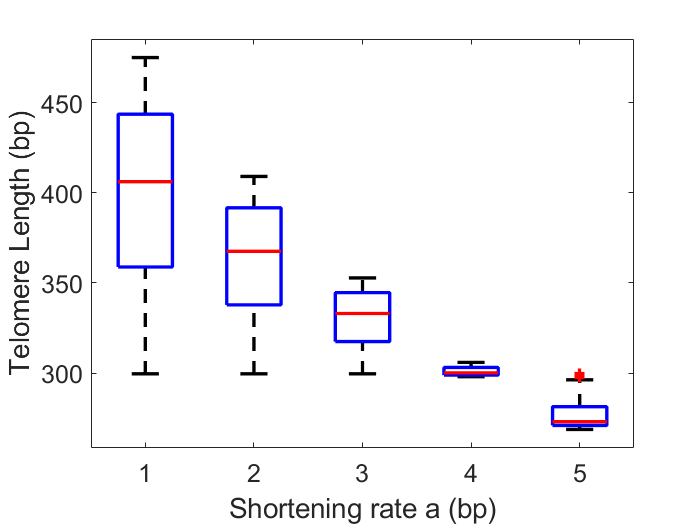

figure(4);
h1 = boxplot(T_avg',(1:5));
set(h1,{'linew'},{2});
ax = gca;
ax.FontSize = 15;
xlabel("Shortening rate a (bp)","FontSize",15);
ylabel("Telomere Length (bp)","FontSize",15);

%title('B');

% Loop

for k = 1:5  % Change k with a for different a values also at end of loop
    
    %p = Prob_arr(a);
    %p = Prob_arr(k);
    %beta = Prob_arr(k);
    for t =1:Tel

    %Initial length from distribution for each telomere
        L(1) = sslen(t);
        %L(1) = 140;
        for i=1:n-1
            % Generating b from geometric distribution with prob p
            %b = geornd(p); % Telomerase processivity % Takes maximum time
            %of execution
            b = Telpro(k);
            B(i+1) = b;
            if (L(i)>=L0)
                %Probability of elongation
                PLn = 1/ (1 + beta*(L(i)-L0));
            else
                PLn = 1;
            end
            if (PLn > rand)
                L(i+1) = (L(i) -a+b);
            else
                L(i+1) = (L(i) - a);
            end
            %L(i+1) = (L(i) - a)*(1-PLn) + (L(i) - a + b)*PLn;
        end
        T(t,:) = L;
        Tp(t,:) = B;
        Hist_Tel(t) = L(end);
    end
    T_avg(k,:) = mean(T); % Change k with a
end

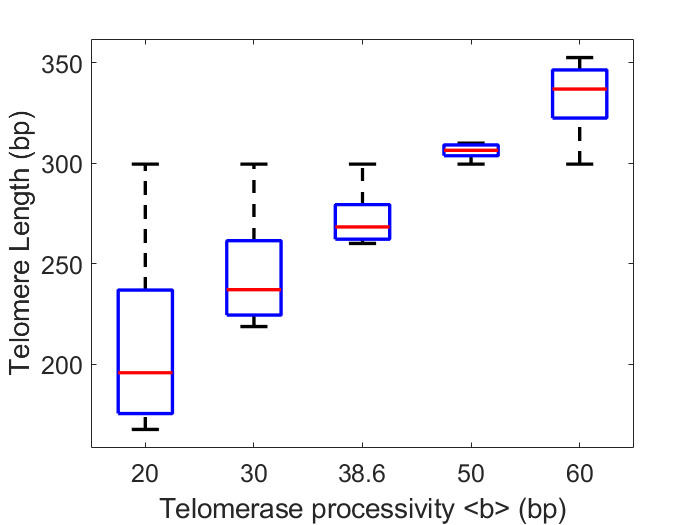


% Plot
figure(5);
h2 = boxplot(T_avg',Telpro);
set(h2,{'linew'},{2});
ax = gca;
ax.FontSize = 15;
%title("2C");
xlabel("Telomerase processivity <b> (bp)",'FontSize',15);
ylabel("Telomere Length (bp)","FontSize",15);

% Loop

for k = 1:5  % Change k with a for different a values also at end of loop
    
    %p = Prob_arr(a);
    %p = Prob_arr(k);
    %beta = Prob_arr(k);
    for t =1:Tel

    %Initial length from distribution for each telomere
        %L(1) = sslen(t);
        L(1) = 140;
        for i=1:n-1
            % Generating b from geometric distribution with prob p
            b = geornd(p); % Telomerase processivity % Takes maximum time
            %of execution
            %b = Telpro(k);
            B(i+1) = b;
            if (L(i)>=L0)
                %Probability of elongation
                PLn = 1/ (1 + beta*(L(i)-L0));
            else
                PLn = 1;
            end
            if (PLn > rand)
                L(i+1) = (L(i) -a+b);
            else
                L(i+1) = (L(i) - a);
            end
            %L(i+1) = (L(i) - a)*(1-PLn) + (L(i) - a + b)*PLn;
        end
        T(t,:) = L;
        Tp(t,:) = B;
        Hist_Tel(t) = L(end);
    end
    T_avg(k,:) = mean(T); % Change k with a
end

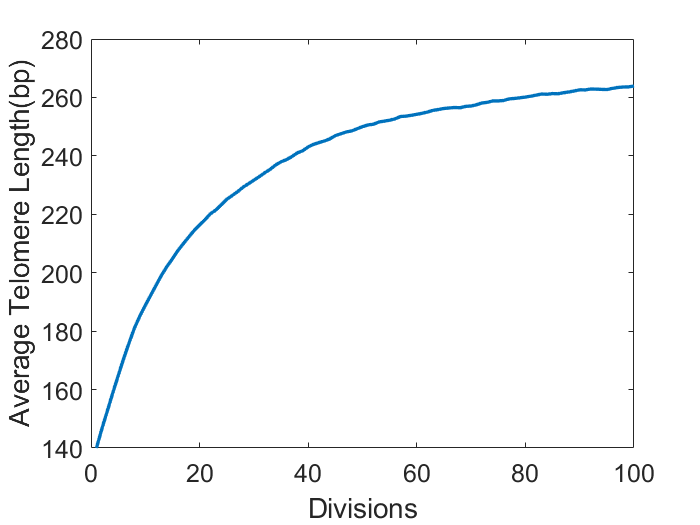

figure(6);
TL_avg = mean(T);
plot(TL_avg,'linewidth',2);
ax = gca;
ax.FontSize = 15;
xlabel("Divisions","FontSize",15);
ylabel("Average Telomere Length(bp)","FontSize",15);

%title("3A. TL dynamics of short telomere","FontSize",15);


% Loop

for k = 1:5  % Change k with a for different a values also at end of loop
    
    %p = Prob_arr(a);
    %p = Prob_arr(k);
    %beta = Prob_arr(k);
    for t =1:Tel

    %Initial length from distribution for each telomere
        %L(1) = sslen(t);
        L(1) = 600;
        for i=1:n-1
            % Generating b from geometric distribution with prob p
            b = geornd(p); % Telomerase processivity % Takes maximum time
            %of execution
            %b = Telpro(k);
            B(i+1) = b;
            if (L(i)>=L0)
                %Probability of elongation
                PLn = 1/ (1 + beta*(L(i)-L0));
            else
                PLn = 1;
            end
            if (PLn > rand)
                L(i+1) = (L(i) -a+b);
            else
                L(i+1) = (L(i) - a);
            end
            %L(i+1) = (L(i) - a)*(1-PLn) + (L(i) - a + b)*PLn;
        end
        T(t,:) = L;
        Tp(t,:) = B;
        Hist_Tel(t) = L(end);
    end
    T_avg(k,:) = mean(T); % Change k with a
end

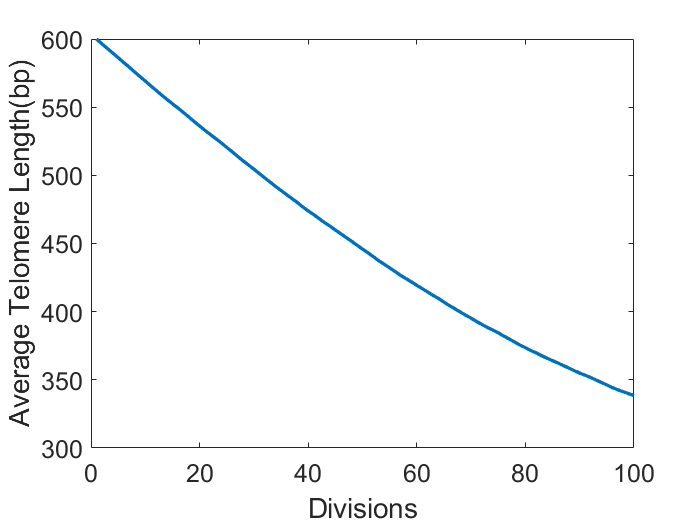

figure(7);
TL_avg = mean(T);
plot(TL_avg,'linewidth',2);
ax = gca;
ax.FontSize = 15;
xlabel("Divisions","FontSize",15);
ylabel("Average Telomere Length(bp)","FontSize",15);

%title("3B. TL dynamics of long telomere");

% Fig 3D
% Loop

for k = 1:5  % Change k with a for different a values also at end of loop
    
    %p = Prob_arr(a);
    %p = Prob_arr(k);
    %beta = Prob_arr(k);
    for t =1:Tel

    %Initial length from distribution for each telomere
        L(1) = sslen(t);
        %L(1) = 140;
        for i=1:n-1
            % Generating b from geometric distribution with prob p
            b = geornd(p); % Telomerase processivity % Takes maximum time
            %of execution
            %b = Telpro(k);
            B(i+1) = b;
            if (L(i)>=L0)
                %Probability of elongation
                PLn = 1/ (1 + beta*(L(i)-L0));
            else
                PLn = 1;
            end
            if (PLn > rand)
                L(i+1) = (L(i) -a+b);
            else
                L(i+1) = (L(i) - a);
            end
            %L(i+1) = (L(i) - a)*(1-PLn) + (L(i) - a + b)*PLn;
        end
        T(t,:) = L;
        Tp(t,:) = B;
        Hist_Tel(t) = L(end);
    end
    T_avg(k,:) = mean(T); % Change k with a
end

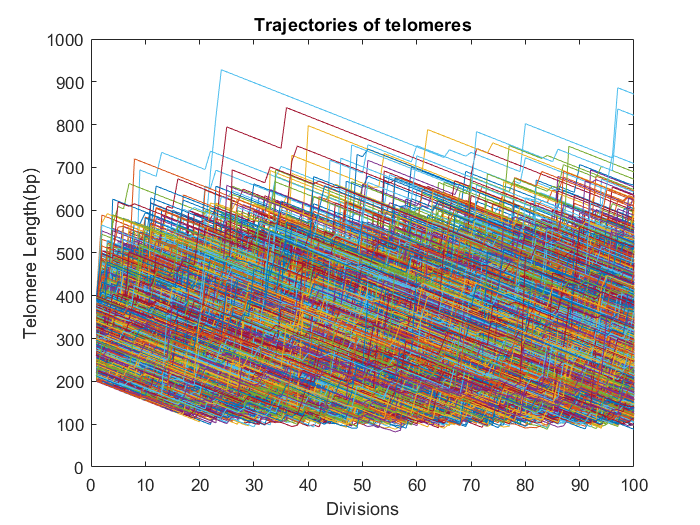

figure(8);
plot(1:n,T);
xlabel("Divisions");
ylabel("Telomere Length(bp)");
title("Trajectories of telomeres");

Tel = 10;    % No. of Telomeres

L = []; % to store Length at each division
T = zeros([Tel,n]); % # of independent telomeres for n division
Tp = zeros([Tel,n]); % Telomerase processivity for telomeres
initlen = 200; % This is starting-/initial length with 200bp
finlen = 400; % This is ending/finishing length with 400 bp
sslen = (finlen-initlen).*rand(100000,1) + initlen; % uniform distribution
B = []; % array to store Telomerase processivity values
PLN = [];
T_avg = zeros(5,n);
Hist_Tel = [];

% Parameters for graph
Telpro = [20 30 38.6 50 60];
Prob_arr = [0.05 0.075 0.09 0.125 0.15];

% Loop

for k = 1:5  % Change k with a for different a values also at end of loop
    
    %p = Prob_arr(a);
    %p = Prob_arr(k);
    %beta = Prob_arr(k);
    for t =1:Tel

    %Initial length from distribution for each telomere
        L(1) = sslen(t);
        %L(1) = 140;
        for i=1:n-1
            % Generating b from geometric distribution with prob p
            b = geornd(p); % Telomerase processivity % Takes maximum time
            %of execution
            %b = Telpro(k);
            B(i+1) = b;
            if (L(i)>=L0)
                %Probability of elongation
                PLn = 1/ (1 + beta*(L(i)-L0));
            else
                PLn = 1;
            end
            if (PLn > rand)
                L(i+1) = (L(i) -a+b);
            else
                L(i+1) = (L(i) - a);
            end
            %L(i+1) = (L(i) - a)*(1-PLn) + (L(i) - a + b)*PLn;
        end
        T(t,:) = L;
        Tp(t,:) = B;
        Hist_Tel(t) = L(end);
    end
    T_avg(k,:) = mean(T); % Change k with a
end

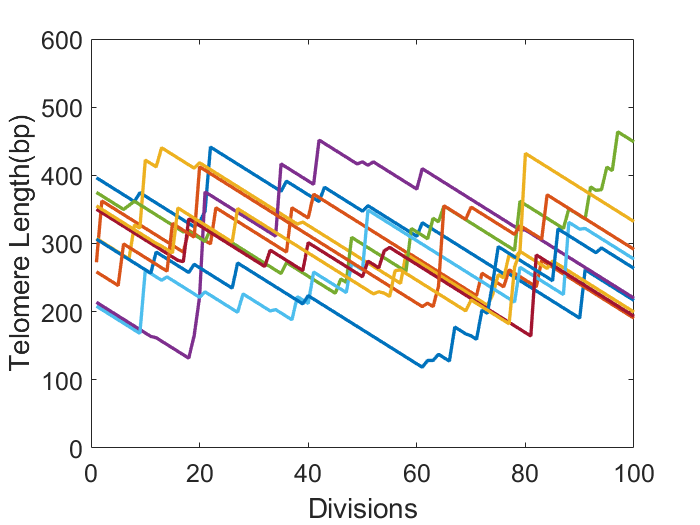


figure(8);
plot(1:n,T,'linewidth',2);
ax = gca;
ax.FontSize = 15;
xlabel("Divisions");
ylim([0 600]);
ylabel("Telomere Length(bp)","FontSize",15);

%title("Trajectories of telomeres","FontSize",15);